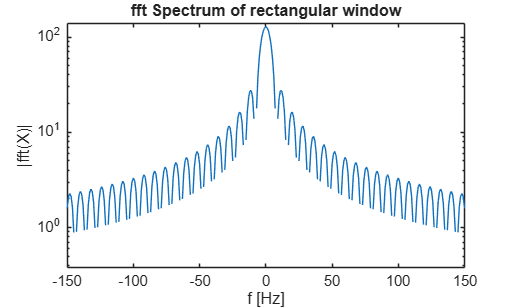

% % Rectangular window:

L = 1024; 
windowLength = 128;
fs = 256;

window = zeros(1, L);
window(1:windowLength) = 1;

freqSignal = abs(fftshift(fft(window)));

semilogy(L/L*(-L/2:L/2-1),freqSignal)
axis([-150 150 0 140])
title("fft Spectrum of rectangular window")
xlabel("f [Hz]")
ylabel("|fft(X)|")

% hold on



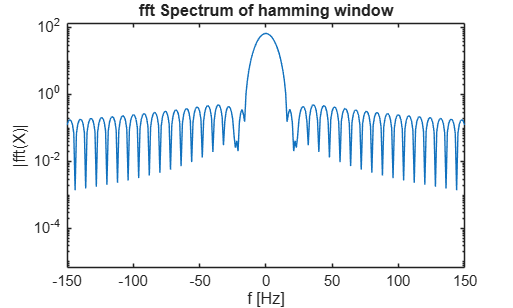

% % Hamming

L = 1024; 
windowLength = 128;
fs = 256;

window = hamming(windowLength);
window = padarray(window, [L-windowLength, 0], 0, 'post');

freqSignal = abs(fftshift(fft(window)));

semilogy(L/L*(-L/2:L/2-1),freqSignal)
axis([-150 150 0 140])
title("fft Spectrum of hamming window")
xlabel("f [Hz]")
ylabel("|fft(X)|")

% hold off


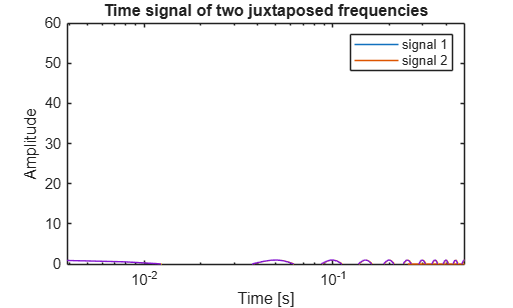

res = fs/L;
freq1 = 20; %Hz
freq2 = freq1 + (res/2);
t = (0:L-1).'/fs;

signal1 = cos(2*pi*freq*t);
signal2 = cos(2*pi*freq2*t);

plot(t,signal1)
hold on
plot(t, signal2)
xlim([0 0.5])
title("Time signal of two juxtaposed frequencies")
xlabel("Time [s]")
ylabel("Amplitude")
legend('signal 1', 'signal 2')
hold off

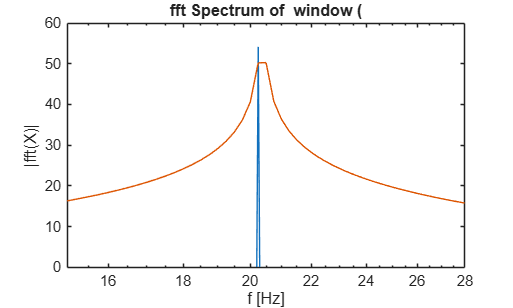


simpleFFTPlot(signal1, fs, [15 28])
hold on
simpleFFTPlot(signal2, fs)
ylim([0 60])
title("fft Spectrum of  window (")
xlabel("f [Hz]")
ylabel("|fft(X)|")

legend('signal 1 ('+ num2str(freq1) + ' Hz)', 'signal 2 (20.125 Hz')

Arrays have incompatible sizes for this operation.

Related documentation

hold off
